# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir


.                         learningCurve.m           submit.m                  
..                        lib                       token.mat                 
ex5.mlx                   linearRegCostFunction.m   trainLinearReg.m          
ex5_companion.mlx         linearRegCostFunction.m~  validationCurve.m         
ex5data1.mat              plotFit.m                 
featureNormalize.m        polyFeatures.m            
fmincg.m                  polyFeatures.m~           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

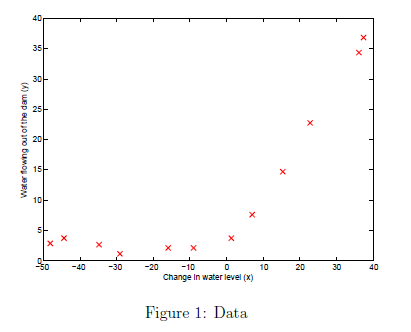

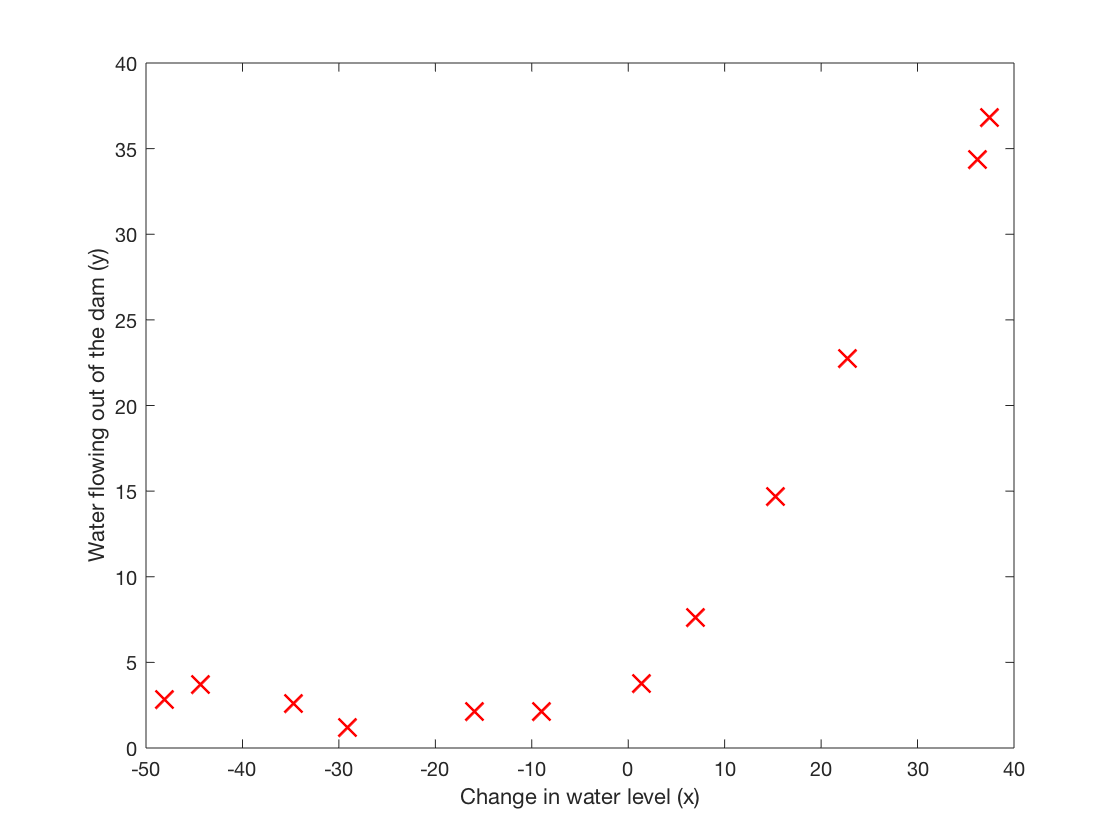

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

Cost at theta = [1 ; 1]: 303.993192

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     5 | Cost: 2.237391e+01
Iteration     6 | Cost: 2.237391e+01
Iteration     7 | Cost: 2.237391e+01
Iteration     8 | Cost: 2.237391e+01
Iteration     9 | Cost: 2.237391e+01
Iteration    11 | Cost: 2.237391e+01


    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

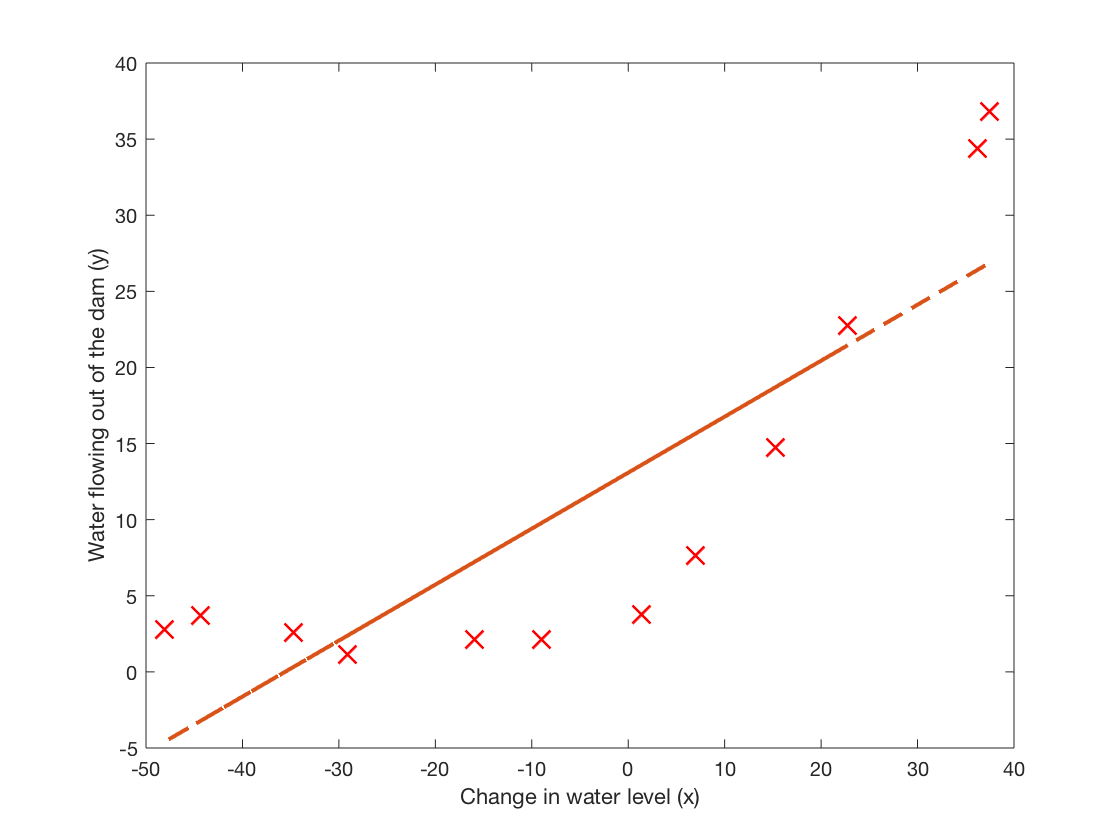

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

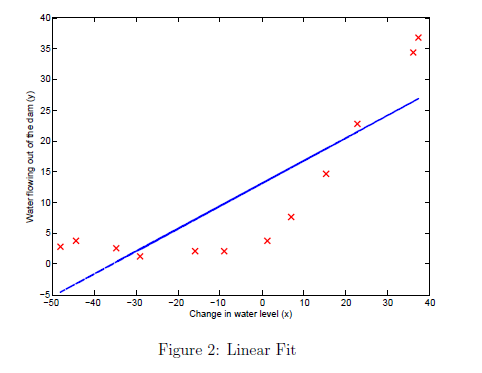

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

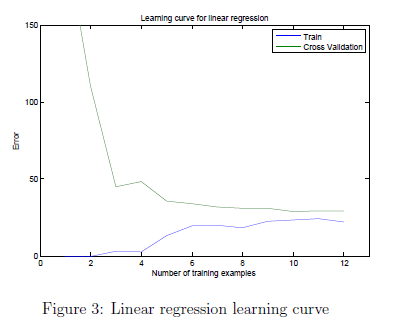

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00


theta =     0.0084
   -0.1334


Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32


theta =     3.2932
    0.0727


Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00


theta =    14.1550
    0.5391


Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.842916e+00
Iteration     7 | Cost: 2.842916e+00
Iteration     8 | Cost: 2.842770e+00
Iteration     9 | Cost: 2.842731e+00
Iteration    10 | Cost: 2.842729e+00
Iteration    11 | Cost: 2.842678e+00


theta =    14.6243
    0.5599


Iteration     1 | Cost: 1.592641e+02
Iteration     2 | Cost: 2.404966e+01
Iteration     3 | Cost: 2.354137e+01
Iteration     4 | Cost: 2.281160e+01
Iteration     5 | Cost: 2.276969e+01
Iteration     6 | Cost: 2.224060e+01
Iteration     7 | Cost: 1.920606e+01
Iteration     8 | Cost: 1.475292e+01
Iteration     9 | Cost: 1.430565e+01
Iteration    10 | Cost: 1.388881e+01
Iteration    11 | Cost: 1.327330e+01
Iteration    12 | Cost: 1.323519e+01
Iteration    13 | Cost: 1.319411e+01
Iteration    14 | Cost: 1.317355e+01
Iteration    15 | Cost: 1.315411e+01
Iteration    16 | Cost: 1.315405e+01
Iteration    17 | Cost: 1.315405e+01
Iteration    18 | Cost: 1.315405e+01
Iteration    19 | Cost: 1.315405e+01
Iteration    20 | Cost: 1.315405e+01
Iteration    21 | Cost: 1.315405e+01
Iteration    22 | Cost: 1.315405e+01
Iteration    23 | Cost: 1.315405e+01


theta =    17.2138
    0.4497


Iteration     1 | Cost: 1.531141e+02
Iteration     2 | Cost: 1.350947e+02
Iteration     3 | Cost: 1.137334e+02
Iteration     4 | Cost: 4.404199e+01
Iteration     5 | Cost: 2.957435e+01
Iteration     6 | Cost: 2.719561e+01
Iteration     7 | Cost: 1.949283e+01
Iteration     8 | Cost: 1.949128e+01
Iteration     9 | Cost: 1.945708e+01
Iteration    10 | Cost: 1.944472e+01
Iteration    11 | Cost: 1.944472e+01
Iteration    12 | Cost: 1.944471e+01
Iteration    13 | Cost: 1.944453e+01
Iteration    14 | Cost: 1.944425e+01
Iteration    15 | Cost: 1.944411e+01
Iteration    16 | Cost: 1.944396e+01
Iteration    17 | Cost: 1.944396e+01
Iteration    18 | Cost: 1.944396e+01
Iteration    19 | Cost: 1.944396e+01
Iteration    20 | Cost: 1.944396e+01
Iteration    21 | Cost: 1.944396e+01
Iteration    22 | Cost: 1.944396e+01
Iteration    23 | Cost: 1.944396e+01
Iteration    25 | Cost: 1.944396e+01
Iteration    26 | Cost: 1.944396e+01


theta =    15.4049
    0.4574


Iteration     1 | Cost: 1.383936e+02
Iteration     2 | Cost: 1.210275e+02
Iteration     3 | Cost: 1.013004e+02
Iteration     4 | Cost: 3.457729e+01
Iteration     5 | Cost: 2.808710e+01
Iteration     6 | Cost: 2.732288e+01
Iteration     7 | Cost: 2.011513e+01
Iteration     8 | Cost: 2.011508e+01
Iteration     9 | Cost: 2.010693e+01
Iteration    10 | Cost: 2.010640e+01
Iteration    11 | Cost: 2.010629e+01
Iteration    12 | Cost: 2.010382e+01
Iteration    13 | Cost: 2.009852e+01
Iteration    14 | Cost: 2.009852e+01
Iteration    15 | Cost: 2.009852e+01
Iteration    16 | Cost: 2.009852e+01
Iteration    17 | Cost: 2.009852e+01


theta =    14.2668
    0.4368


Iteration     1 | Cost: 1.237772e+02
Iteration     2 | Cost: 1.202532e+02
Iteration     3 | Cost: 1.195134e+02
Iteration     4 | Cost: 9.334231e+01
Iteration     5 | Cost: 4.813526e+01
Iteration     6 | Cost: 2.650400e+01
Iteration     7 | Cost: 1.927314e+01
Iteration     8 | Cost: 1.826693e+01
Iteration     9 | Cost: 1.817331e+01
Iteration    10 | Cost: 1.817289e+01
Iteration    11 | Cost: 1.817288e+01
Iteration    12 | Cost: 1.817286e+01
Iteration    13 | Cost: 1.817286e+01
Iteration    14 | Cost: 1.817286e+01
Iteration    15 | Cost: 1.817286e+01
Iteration    16 | Cost: 1.817286e+01
Iteration    17 | Cost: 1.817286e+01
Iteration    18 | Cost: 1.817286e+01
Iteration    20 | Cost: 1.817286e+01
Iteration    22 | Cost: 1.817286e+01


theta =    14.6234
    0.4231


Iteration     1 | Cost: 1.089984e+02
Iteration     2 | Cost: 1.064701e+02
Iteration     3 | Cost: 1.054742e+02
Iteration     4 | Cost: 2.266786e+01
Iteration     5 | Cost: 2.266786e+01
Iteration     6 | Cost: 2.266758e+01
Iteration     7 | Cost: 2.260941e+01
Iteration     8 | Cost: 2.260941e+01
Iteration     9 | Cost: 2.260941e+01


theta =    13.2966
    0.4130


Iteration     1 | Cost: 1.108611e+02
Iteration     2 | Cost: 2.497543e+01
Iteration     3 | Cost: 2.496421e+01
Iteration     4 | Cost: 2.494838e+01
Iteration     5 | Cost: 2.493176e+01
Iteration     6 | Cost: 2.490655e+01
Iteration     7 | Cost: 2.474451e+01
Iteration     8 | Cost: 2.326187e+01
Iteration     9 | Cost: 2.326187e+01
Iteration    10 | Cost: 2.326182e+01
Iteration    11 | Cost: 2.326181e+01
Iteration    12 | Cost: 2.326180e+01
Iteration    13 | Cost: 2.326177e+01
Iteration    14 | Cost: 2.326166e+01
Iteration    15 | Cost: 2.326150e+01
Iteration    16 | Cost: 2.326149e+01
Iteration    17 | Cost: 2.326148e+01
Iteration    18 | Cost: 2.326147e+01
Iteration    19 | Cost: 2.326147e+01
Iteration    20 | Cost: 2.326147e+01
Iteration    21 | Cost: 2.326146e+01
Iteration    22 | Cost: 2.326146e+01
Iteration    23 | Cost: 2.326146e+01
Iteration    24 | Cost: 2.326146e+01
Iteration    25 | Cost: 2.326146e+01
Iteration    26 | Cost: 2.326146e+01
Iteration    27 | Cost: 2.326146e+01
I

theta =    13.8537
    0.3778


Iteration     1 | Cost: 1.023394e+02
Iteration     2 | Cost: 2.443039e+01
Iteration     3 | Cost: 2.443033e+01
Iteration     4 | Cost: 2.442972e+01
Iteration     5 | Cost: 2.441042e+01
Iteration     6 | Cost: 2.435852e+01
Iteration     7 | Cost: 2.431735e+01
Iteration     8 | Cost: 2.431733e+01
Iteration     9 | Cost: 2.431727e+01
Iteration    10 | Cost: 2.431725e+01
Iteration    11 | Cost: 2.431725e+01


theta =    12.9372
    0.3634


Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01
Iteration     5 | Cost: 2.237391e+01
Iteration     6 | Cost: 2.237391e+01
Iteration     7 | Cost: 2.237391e+01
Iteration     8 | Cost: 2.237391e+01
Iteration     9 | Cost: 2.237391e+01
Iteration    11 | Cost: 2.237391e+01


theta =    13.0879
    0.3678


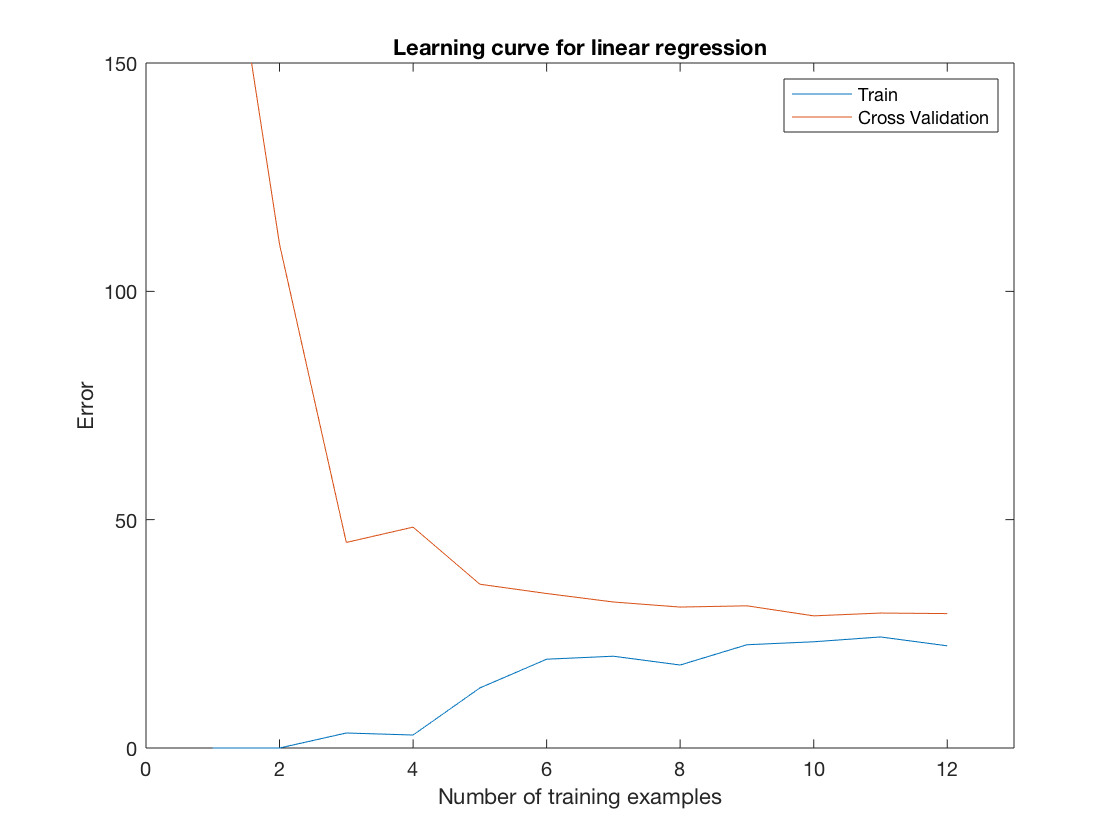


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818


## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.412184e-01
Iteration    11 | Cost: 7.601959e-01
Iteration    12 | Cost: 6.467547e-01
Iteration    13 | Cost: 5.845731e-01
Iteration    14 | Cost: 5.493740e-01
Iteration    15 | Cost: 5.069875e-01
Iteration    16 | Cost: 4.814302e-01
Iteration    17 | Cost: 4.729695e-01
Iteration    18 | Cost: 4.653825e-01
Iteration    19 | Cost: 4.598388e-01
Iteration    20 | Cost: 4.484805e-01
Iteration    21 | Cost: 4.248037e-01
Iteration    22 | Cost: 4.025183e-01
Iteration    23 | Cost: 3.940115e-01
Iteration    24 | Cost: 3.817325e-01
Iteration    25 | Cost: 3.813497e-01
Iteration    26 | Cost: 3.781449e-01
Iteration    27 | Cost: 3.766117e-01
I

    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

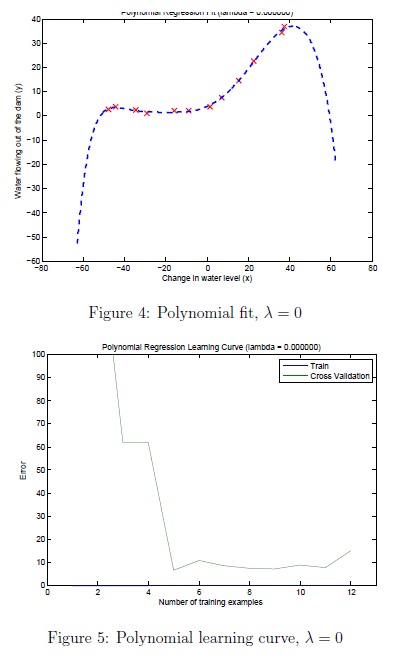

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

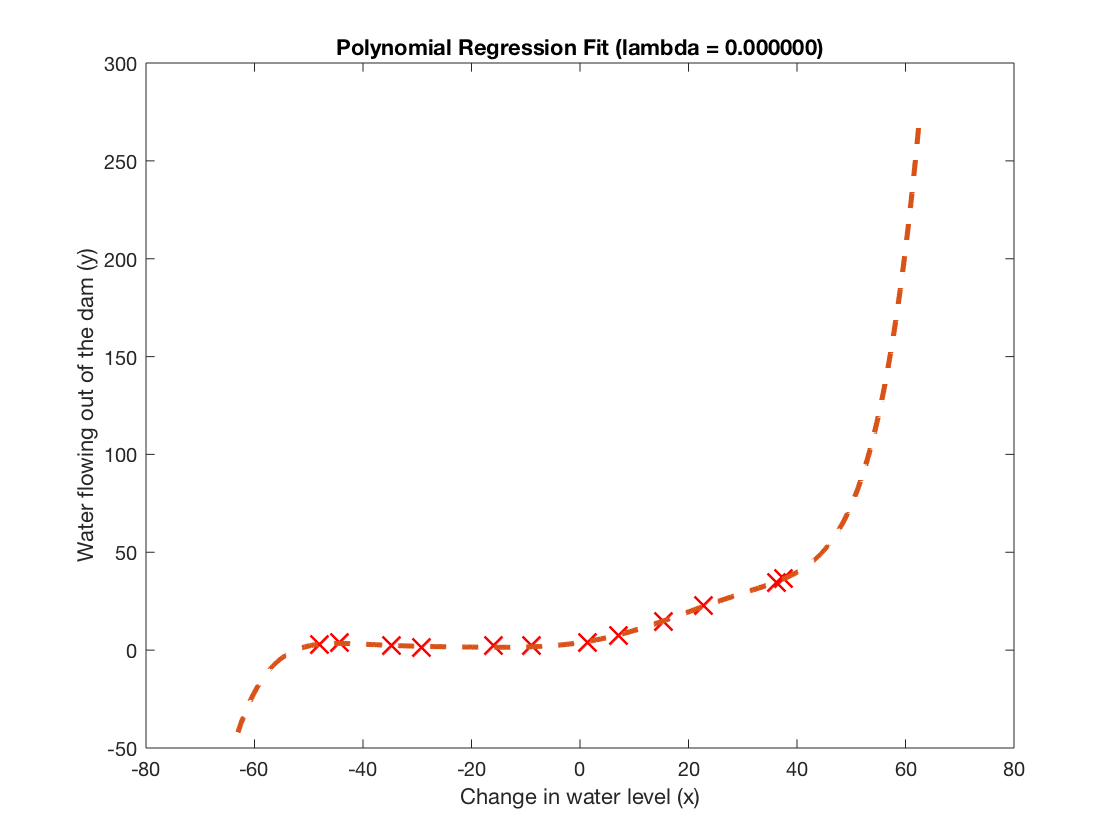

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 3.386454e-01
Iteration     2 | Cost: 9.860761e-32
Iteration     4 | Cost: 0.000000e+00


theta =     0.6989
   -0.2531
   -0.5278
    0.1274
   -0.4936
    0.2143
   -0.4130
    0.2408
   -0.3554


Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 4.560072e-11
Iteration     5 | Cost: 4.560059e-11
Iteration     6 | Cost: 2.309960e-11
Iteration     7 | Cost: 1.551252e-14
Iteration     8 | Cost: 1.550239e-14
Iteration     9 | Cost: 7.917902e-15
Iteration    10 | Cost: 5.482829e-17
Iteration    11 | Cost: 3.321856e-17
Iteration    12 | Cost: 4.062935e-18
Iteration    13 | Cost: 3.711338e-18
Iteration    14 | Cost: 9.611423e-19
Iteration    15 | Cost: 5.369185e-29
Iteration    16 | Cost: 1.232595e-32
Iteration    17 | Cost: 0.000000e+00


theta =     0.5958
   -0.0733
   -0.6941
    0.2475
   -0.5432
    0.2515
   -0.4021
    0.2340
   -0.3222


Iteration     1 | Cost: 3.023381e+01
Iteration     2 | Cost: 9.745401e-01
Iteration     3 | Cost: 4.827305e-01
Iteration     4 | Cost: 1.170249e-02
Iteration     5 | Cost: 9.696908e-04
Iteration     6 | Cost: 5.299258e-04
Iteration     7 | Cost: 1.985836e-04
Iteration     8 | Cost: 6.032119e-05
Iteration     9 | Cost: 6.225212e-07
Iteration    10 | Cost: 3.894758e-07
Iteration    11 | Cost: 7.703724e-08
Iteration    12 | Cost: 5.688321e-08
Iteration    13 | Cost: 5.385450e-09
Iteration    14 | Cost: 1.603656e-10
Iteration    15 | Cost: 1.516867e-11
Iteration    16 | Cost: 9.627464e-12
Iteration    17 | Cost: 2.794098e-12
Iteration    18 | Cost: 7.766256e-13
Iteration    19 | Cost: 1.571268e-13
Iteration    20 | Cost: 2.248292e-16
Iteration    21 | Cost: 5.079312e-17
Iteration    22 | Cost: 1.499570e-17
Iteration    23 | Cost: 3.850978e-18
Iteration    24 | Cost: 3.415932e-29
Iteration    25 | Cost: 3.040401e-31
Iteration    26 | Cost: 1.396941e-31
Iteration    27 | Cost: 7.395571e-32
I

theta =     6.3942
    6.0725
    6.1249
    5.6590
    2.6152
    5.0238
    0.2492
    4.2528
   -1.0254


Iteration     1 | Cost: 7.960488e-01
Iteration     2 | Cost: 2.114171e-01
Iteration     3 | Cost: 2.702642e-02
Iteration     4 | Cost: 3.974598e-19
Iteration     5 | Cost: 3.036884e-25
Iteration     6 | Cost: 1.125879e-25
Iteration     7 | Cost: 7.950239e-28
Iteration     8 | Cost: 6.303492e-28


theta =     6.5574
    7.5559
    6.9020
    5.1406
    1.9603
    3.8532
   -0.9940
    3.0128
   -2.2925


Iteration     1 | Cost: 9.143237e+01
Iteration     2 | Cost: 2.751413e+01
Iteration     3 | Cost: 3.422469e+00
Iteration     4 | Cost: 1.700112e+00
Iteration     5 | Cost: 1.451341e+00
Iteration     6 | Cost: 9.230357e-01
Iteration     7 | Cost: 3.076245e-01
Iteration     8 | Cost: 1.604165e-01
Iteration     9 | Cost: 1.052956e-01
Iteration    10 | Cost: 7.440046e-02
Iteration    11 | Cost: 6.810514e-02
Iteration    12 | Cost: 6.457708e-02
Iteration    13 | Cost: 6.401566e-02
Iteration    14 | Cost: 6.009503e-02
Iteration    15 | Cost: 5.650623e-02
Iteration    16 | Cost: 3.894453e-02
Iteration    17 | Cost: 3.592528e-02
Iteration    18 | Cost: 3.539824e-02
Iteration    19 | Cost: 3.315735e-02
Iteration    20 | Cost: 3.260791e-02
Iteration    21 | Cost: 3.107633e-02
Iteration    22 | Cost: 2.691840e-02
Iteration    23 | Cost: 2.598735e-02
Iteration    24 | Cost: 2.590794e-02
Iteration    25 | Cost: 2.551267e-02
Iteration    26 | Cost: 2.534965e-02
Iteration    27 | Cost: 2.341718e-02
I

theta =    10.4186
    8.3490
    5.5793
    5.1722
    2.6394
    2.0795
    1.0135
    0.1538
    0.4292


Iteration     1 | Cost: 6.685771e+01
Iteration     2 | Cost: 1.216701e+01
Iteration     3 | Cost: 1.795979e+00
Iteration     4 | Cost: 6.292963e-01
Iteration     5 | Cost: 2.225698e-01
Iteration     6 | Cost: 5.075312e-02
Iteration     7 | Cost: 4.971823e-02
Iteration     8 | Cost: 4.887205e-02
Iteration     9 | Cost: 4.848315e-02
Iteration    10 | Cost: 4.805711e-02
Iteration    11 | Cost: 4.762102e-02
Iteration    12 | Cost: 4.708698e-02
Iteration    13 | Cost: 4.655854e-02
Iteration    14 | Cost: 4.629603e-02
Iteration    15 | Cost: 4.628185e-02
Iteration    16 | Cost: 4.610115e-02
Iteration    17 | Cost: 4.593608e-02
Iteration    18 | Cost: 4.585757e-02
Iteration    19 | Cost: 4.558511e-02
Iteration    20 | Cost: 4.528027e-02
Iteration    21 | Cost: 4.495069e-02
Iteration    22 | Cost: 4.460798e-02
Iteration    23 | Cost: 4.228801e-02
Iteration    24 | Cost: 3.930391e-02
Iteration    25 | Cost: 3.762048e-02
Iteration    26 | Cost: 3.636347e-02
Iteration    27 | Cost: 3.585178e-02
I

theta =     9.2563
    4.9017
    9.2422
   11.3625
   -2.2058
    2.9314
    0.2118
   -4.1345
    2.6452


Iteration     1 | Cost: 7.107198e+01
Iteration     2 | Cost: 8.740445e+00
Iteration     3 | Cost: 7.522075e+00
Iteration     4 | Cost: 2.677520e+00
Iteration     5 | Cost: 2.048621e+00
Iteration     6 | Cost: 1.327873e+00
Iteration     7 | Cost: 1.158691e+00
Iteration     8 | Cost: 1.089799e+00
Iteration     9 | Cost: 8.703652e-01
Iteration    10 | Cost: 6.342126e-01
Iteration    11 | Cost: 6.159212e-01
Iteration    12 | Cost: 5.623894e-01
Iteration    13 | Cost: 5.111742e-01
Iteration    14 | Cost: 3.921831e-01
Iteration    15 | Cost: 3.698890e-01
Iteration    16 | Cost: 3.237655e-01
Iteration    17 | Cost: 3.127834e-01
Iteration    18 | Cost: 2.742294e-01
Iteration    19 | Cost: 2.595213e-01
Iteration    20 | Cost: 2.394126e-01
Iteration    21 | Cost: 2.362152e-01
Iteration    22 | Cost: 2.317582e-01
Iteration    23 | Cost: 2.271156e-01
Iteration    24 | Cost: 1.985156e-01
Iteration    25 | Cost: 1.634943e-01
Iteration    26 | Cost: 1.254476e-01
Iteration    27 | Cost: 1.206516e-01
I

theta =    10.9298
   12.7430
   10.2232
   -1.5416
   -7.5744
    2.9156
    1.0239
    2.8608
    6.3815


Iteration     1 | Cost: 6.233475e+01
Iteration     2 | Cost: 6.252861e+00
Iteration     3 | Cost: 3.386639e+00
Iteration     4 | Cost: 1.849186e+00
Iteration     5 | Cost: 1.488263e+00
Iteration     6 | Cost: 1.304655e+00
Iteration     7 | Cost: 1.227710e+00
Iteration     8 | Cost: 1.135255e+00
Iteration     9 | Cost: 1.035629e+00
Iteration    10 | Cost: 9.292646e-01
Iteration    11 | Cost: 7.582864e-01
Iteration    12 | Cost: 6.949027e-01
Iteration    13 | Cost: 4.850758e-01
Iteration    14 | Cost: 4.396008e-01
Iteration    15 | Cost: 3.164280e-01
Iteration    16 | Cost: 1.449082e-01
Iteration    17 | Cost: 1.309203e-01
Iteration    18 | Cost: 1.200797e-01
Iteration    19 | Cost: 1.099894e-01
Iteration    20 | Cost: 1.069281e-01
Iteration    21 | Cost: 1.045676e-01
Iteration    22 | Cost: 1.042434e-01
Iteration    23 | Cost: 1.028115e-01
Iteration    24 | Cost: 1.023863e-01
Iteration    25 | Cost: 1.005140e-01
Iteration    26 | Cost: 9.994052e-02
Iteration    27 | Cost: 9.920663e-02
I

theta =    11.3192
   13.2361
    8.0463
   -2.7820
   -2.9943
    0.7332
    2.9352
    5.4793
    1.9913


Iteration     1 | Cost: 5.922449e+01
Iteration     2 | Cost: 5.854872e+00
Iteration     3 | Cost: 5.301112e+00
Iteration     4 | Cost: 2.893773e+00
Iteration     5 | Cost: 1.997938e+00
Iteration     6 | Cost: 1.514096e+00
Iteration     7 | Cost: 1.513891e+00
Iteration     8 | Cost: 1.375440e+00
Iteration     9 | Cost: 1.303284e+00
Iteration    10 | Cost: 9.804273e-01
Iteration    11 | Cost: 8.970704e-01
Iteration    12 | Cost: 8.665588e-01
Iteration    13 | Cost: 5.873525e-01
Iteration    14 | Cost: 4.932797e-01
Iteration    15 | Cost: 4.367776e-01
Iteration    16 | Cost: 3.578298e-01
Iteration    17 | Cost: 3.562305e-01
Iteration    18 | Cost: 3.510096e-01
Iteration    19 | Cost: 3.468323e-01
Iteration    20 | Cost: 3.456480e-01
Iteration    21 | Cost: 3.416694e-01
Iteration    22 | Cost: 3.399199e-01
Iteration    23 | Cost: 3.363236e-01
Iteration    24 | Cost: 3.327545e-01
Iteration    25 | Cost: 3.304463e-01
Iteration    26 | Cost: 3.272905e-01
Iteration    27 | Cost: 3.255180e-01
I

theta =    10.9750
   12.0486
   14.0121
    3.6747
  -12.4195
   -5.4697
    4.1898
    4.5692
    2.7358


Iteration     1 | Cost: 5.599132e+01
Iteration     2 | Cost: 1.160850e+01
Iteration     3 | Cost: 5.777511e+00
Iteration     4 | Cost: 3.138721e+00
Iteration     5 | Cost: 1.743808e+00
Iteration     6 | Cost: 1.324477e+00
Iteration     7 | Cost: 1.115175e+00
Iteration     8 | Cost: 8.331651e-01
Iteration     9 | Cost: 7.154431e-01
Iteration    10 | Cost: 6.491382e-01
Iteration    11 | Cost: 6.421455e-01
Iteration    12 | Cost: 4.594554e-01
Iteration    13 | Cost: 3.915120e-01
Iteration    14 | Cost: 3.307670e-01
Iteration    15 | Cost: 3.300309e-01
Iteration    16 | Cost: 3.270170e-01
Iteration    17 | Cost: 3.263105e-01
Iteration    18 | Cost: 3.232863e-01
Iteration    19 | Cost: 3.227537e-01
Iteration    20 | Cost: 3.213437e-01
Iteration    21 | Cost: 3.199773e-01
Iteration    22 | Cost: 3.138206e-01
Iteration    23 | Cost: 3.132637e-01
Iteration    24 | Cost: 3.124458e-01
Iteration    25 | Cost: 3.117808e-01
Iteration    26 | Cost: 3.094734e-01
Iteration    27 | Cost: 3.084241e-01
I

theta =    11.1197
   11.7354
   12.6609
    6.2613
   -8.9346
   -7.9214
    6.0058
    2.7377
   -3.1469


Iteration     1 | Cost: 7.186879e+01
Iteration     2 | Cost: 2.278130e+01
Iteration     3 | Cost: 4.970159e+00
Iteration     4 | Cost: 1.355413e+00
Iteration     5 | Cost: 1.252814e+00
Iteration     6 | Cost: 1.187952e+00
Iteration     7 | Cost: 1.157390e+00
Iteration     8 | Cost: 1.037496e+00
Iteration     9 | Cost: 9.195845e-01
Iteration    10 | Cost: 8.848918e-01
Iteration    11 | Cost: 8.342791e-01
Iteration    12 | Cost: 7.925264e-01
Iteration    13 | Cost: 6.665888e-01
Iteration    14 | Cost: 5.321433e-01
Iteration    15 | Cost: 4.795218e-01
Iteration    16 | Cost: 4.162790e-01
Iteration    17 | Cost: 3.755044e-01
Iteration    18 | Cost: 3.574733e-01
Iteration    19 | Cost: 3.373114e-01
Iteration    20 | Cost: 3.276408e-01
Iteration    21 | Cost: 3.204686e-01
Iteration    22 | Cost: 3.201919e-01
Iteration    23 | Cost: 3.191403e-01
Iteration    24 | Cost: 3.183903e-01
Iteration    25 | Cost: 3.173610e-01
Iteration    26 | Cost: 3.163294e-01
Iteration    27 | Cost: 3.140179e-01
I

theta =    11.1088
   11.3304
   15.6554
    9.8846
  -22.4003
  -20.6836
   21.3442
   15.5386
   -4.7029


Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.412184e-01
Iteration    11 | Cost: 7.601959e-01
Iteration    12 | Cost: 6.467547e-01
Iteration    13 | Cost: 5.845731e-01
Iteration    14 | Cost: 5.493740e-01
Iteration    15 | Cost: 5.069875e-01
Iteration    16 | Cost: 4.814302e-01
Iteration    17 | Cost: 4.729695e-01
Iteration    18 | Cost: 4.653825e-01
Iteration    19 | Cost: 4.598388e-01
Iteration    20 | Cost: 4.484805e-01
Iteration    21 | Cost: 4.248037e-01
Iteration    22 | Cost: 4.025183e-01
Iteration    23 | Cost: 3.940115e-01
Iteration    24 | Cost: 3.817325e-01
Iteration    25 | Cost: 3.813497e-01
Iteration    26 | Cost: 3.781449e-01
Iteration    27 | Cost: 3.766117e-01
I

theta =    11.2242
   12.1327
   16.7808
    9.0689
  -22.4242
  -20.9409
   16.3299
   15.6677
   -0.9852


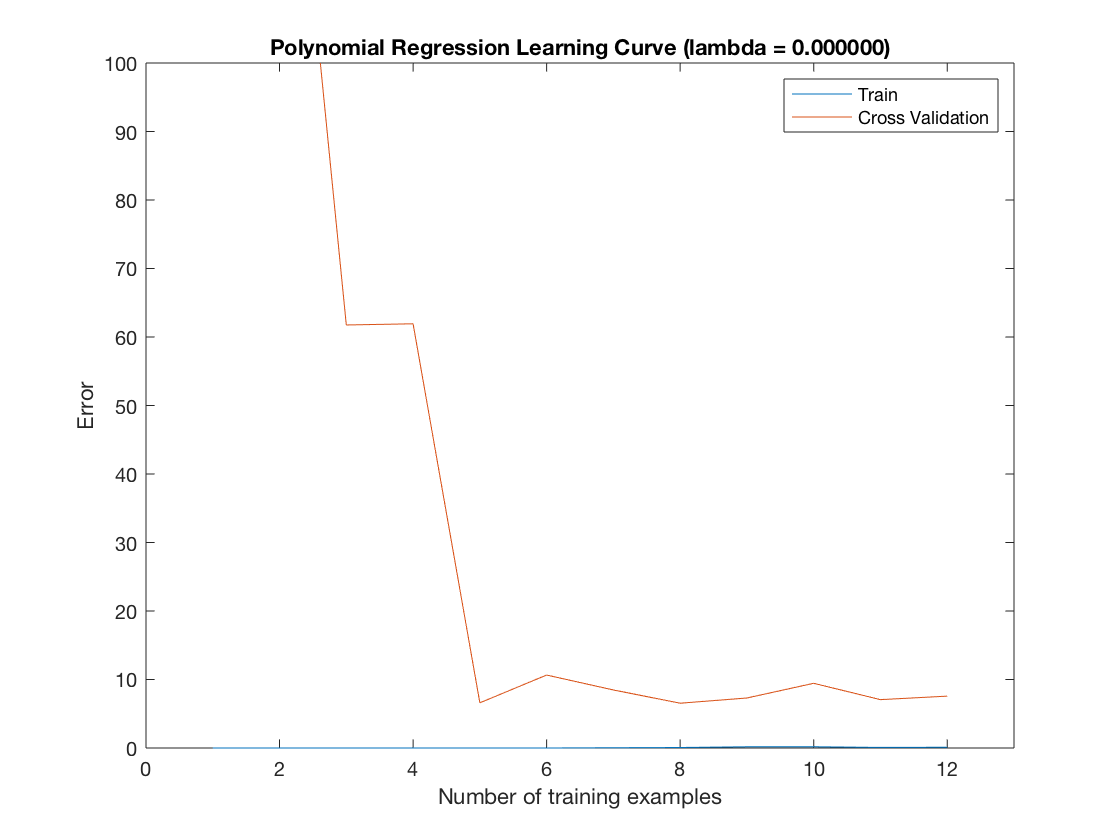

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 100;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 1.218518e+02
Iteration     2 | Cost: 8.964311e+01
Iteration     3 | Cost: 7.058516e+01
Iteration     4 | Cost: 6.856329e+01
Iteration     5 | Cost: 6.804592e+01
Iteration     6 | Cost: 6.674325e+01
Iteration     7 | Cost: 6.673462e+01
Iteration     8 | Cost: 6.673461e+01
Iteration     9 | Cost: 6.673326e+01
Iteration    10 | Cost: 6.673321e+01
Iteration    11 | Cost: 6.673316e+01
Iteration    12 | Cost: 6.673316e+01
Iteration    13 | Cost: 6.673316e+01
Iteration    14 | Cost: 6.673316e+01
Iteration    15 | Cost: 6.673316e+01
Iteration    16 | Cost: 6.673316e+01
Iteration    17 | Cost: 6.673316e+01
Iteration    18 | Cost: 6.673316e+01
Iteration    19 | Cost: 6.673316e+01
Iteration    20 | Cost: 6.673316e+01
Iteration    21 | Cost: 6.673316e+01
Iteration    22 | Cost: 6.673316e+01
Iteration    23 | Cost: 6.673316e+01


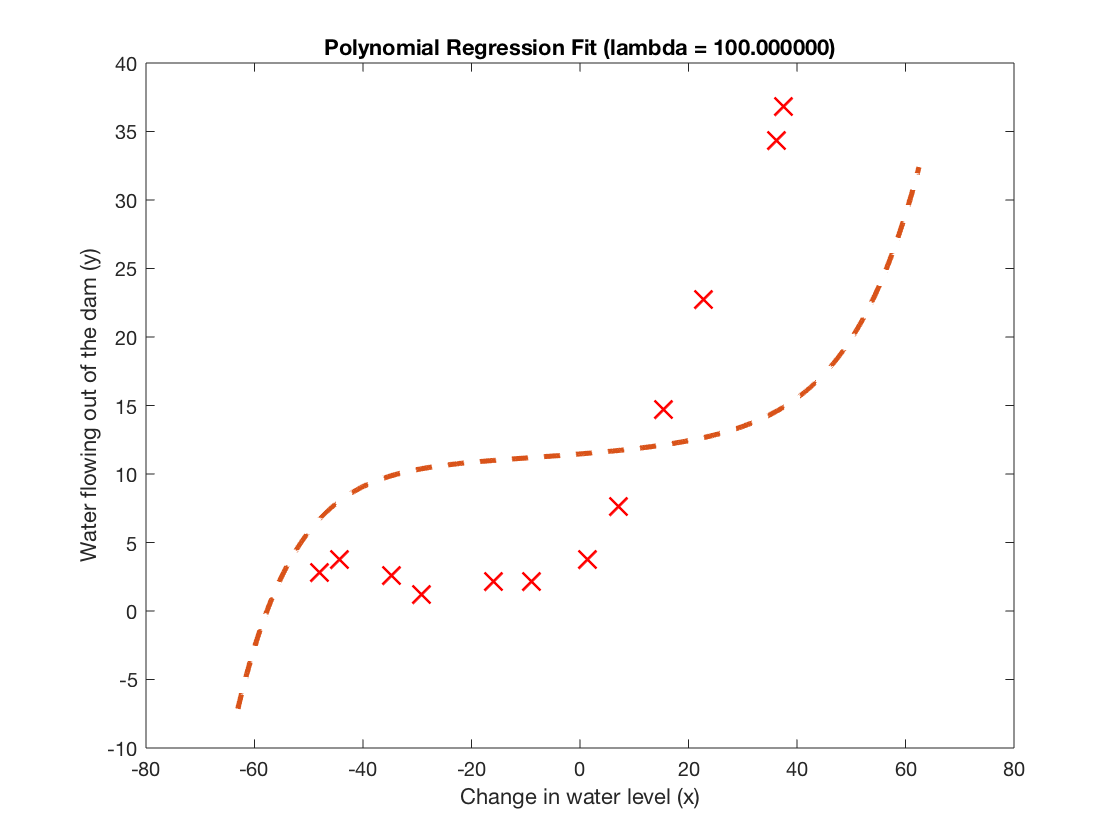


% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 2.178715e+00
Iteration     2 | Cost: 8.453521e-29
Iteration     3 | Cost: 7.335931e-29
Iteration     4 | Cost: 1.739992e-29
Iteration     5 | Cost: 8.163104e-30
Iteration     6 | Cost: 4.192685e-30
Iteration     7 | Cost: 1.326431e-31
Iteration     8 | Cost: 1.001718e-31


theta =     2.1343
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


Iteration     1 | Cost: 1.377219e+00
Iteration     2 | Cost: 1.913835e-01
Iteration     3 | Cost: 1.909083e-01
Iteration     4 | Cost: 1.574826e-01
Iteration     5 | Cost: 1.167971e-01
Iteration     6 | Cost: 1.167255e-01
Iteration     7 | Cost: 1.160132e-01
Iteration     8 | Cost: 1.151354e-01
Iteration     9 | Cost: 1.149515e-01
Iteration    10 | Cost: 1.148641e-01
Iteration    11 | Cost: 1.147780e-01
Iteration    12 | Cost: 1.147779e-01
Iteration    13 | Cost: 1.147779e-01
Iteration    14 | Cost: 1.147779e-01
Iteration    15 | Cost: 1.147779e-01
Iteration    16 | Cost: 1.147779e-01
Iteration    17 | Cost: 1.147779e-01
Iteration    18 | Cost: 1.147779e-01
Iteration    19 | Cost: 1.147779e-01
Iteration    20 | Cost: 1.147779e-01
Iteration    21 | Cost: 1.147779e-01
Iteration    22 | Cost: 1.147779e-01
Iteration    24 | Cost: 1.147779e-01


theta =     1.6519
    0.0021
   -0.0036
    0.0021
   -0.0018
    0.0010
   -0.0007
    0.0004
   -0.0003


Iteration     1 | Cost: 1.832536e+02
Iteration     2 | Cost: 1.261509e+02
Iteration     3 | Cost: 1.245625e+02
Iteration     4 | Cost: 1.132056e+02
Iteration     5 | Cost: 1.127825e+02
Iteration     6 | Cost: 1.127823e+02
Iteration     7 | Cost: 1.127823e+02
Iteration     8 | Cost: 1.127823e+02
Iteration     9 | Cost: 1.127823e+02
Iteration    10 | Cost: 1.127823e+02
Iteration    11 | Cost: 1.127823e+02
Iteration    12 | Cost: 1.127823e+02
Iteration    13 | Cost: 1.127823e+02
Iteration    14 | Cost: 1.127823e+02
Iteration    15 | Cost: 1.127823e+02
Iteration    16 | Cost: 1.127823e+02
Iteration    17 | Cost: 1.127823e+02
Iteration    18 | Cost: 1.127823e+02
Iteration    19 | Cost: 1.127823e+02
Iteration    20 | Cost: 1.127823e+02
Iteration    21 | Cost: 1.127823e+02
Iteration    23 | Cost: 1.127823e+02
Iteration    24 | Cost: 1.127823e+02
Iteration    25 | Cost: 1.127823e+02
Iteration    26 | Cost: 1.127823e+02
Iteration    27 | Cost: 1.127823e+02
Iteration    29 | Cost: 1.127823e+02
I

theta =    12.4156
    0.4072
    0.1957
    0.2671
    0.1559
    0.1619
    0.1030
    0.0948
    0.0635


Iteration     1 | Cost: 2.733059e+02
Iteration     2 | Cost: 1.372421e+02
Iteration     3 | Cost: 1.346771e+02
Iteration     4 | Cost: 1.335349e+02
Iteration     5 | Cost: 1.326975e+02
Iteration     6 | Cost: 1.326966e+02
Iteration     7 | Cost: 1.326525e+02
Iteration     8 | Cost: 1.326430e+02
Iteration     9 | Cost: 1.326354e+02
Iteration    10 | Cost: 1.326237e+02
Iteration    11 | Cost: 1.326207e+02
Iteration    12 | Cost: 1.326204e+02
Iteration    13 | Cost: 1.326203e+02
Iteration    14 | Cost: 1.326203e+02
Iteration    15 | Cost: 1.326203e+02
Iteration    16 | Cost: 1.326203e+02
Iteration    17 | Cost: 1.326203e+02
Iteration    18 | Cost: 1.326203e+02
Iteration    19 | Cost: 1.326203e+02
Iteration    20 | Cost: 1.326203e+02
Iteration    21 | Cost: 1.326203e+02
Iteration    22 | Cost: 1.326203e+02
Iteration    23 | Cost: 1.326203e+02
Iteration    25 | Cost: 1.326203e+02


theta =    17.9091
    0.6199
    0.3170
    0.4198
    0.2610
    0.2648
    0.1786
    0.1619
    0.1143


Iteration     1 | Cost: 2.219277e+02
Iteration     2 | Cost: 1.869369e+02
Iteration     3 | Cost: 1.182851e+02
Iteration     4 | Cost: 1.173776e+02
Iteration     5 | Cost: 1.173495e+02
Iteration     6 | Cost: 1.173493e+02
Iteration     7 | Cost: 1.173493e+02
Iteration     8 | Cost: 1.173492e+02
Iteration     9 | Cost: 1.173492e+02
Iteration    10 | Cost: 1.173491e+02
Iteration    11 | Cost: 1.173491e+02
Iteration    12 | Cost: 1.173491e+02
Iteration    13 | Cost: 1.173491e+02
Iteration    14 | Cost: 1.173491e+02
Iteration    15 | Cost: 1.173491e+02
Iteration    16 | Cost: 1.173491e+02
Iteration    17 | Cost: 1.173491e+02
Iteration    18 | Cost: 1.173491e+02
Iteration    19 | Cost: 1.173491e+02
Iteration    20 | Cost: 1.173491e+02
Iteration    21 | Cost: 1.173491e+02
Iteration    22 | Cost: 1.173491e+02
Iteration    23 | Cost: 1.173491e+02
Iteration    25 | Cost: 1.173491e+02
Iteration    26 | Cost: 1.173491e+02


theta =    15.3407
    0.7572
    0.1794
    0.6250
    0.0672
    0.5005
   -0.0464
    0.4125
   -0.1284


Iteration     1 | Cost: 1.849990e+02
Iteration     2 | Cost: 1.558036e+02
Iteration     3 | Cost: 1.170396e+02
Iteration     4 | Cost: 1.169578e+02
Iteration     5 | Cost: 1.151019e+02
Iteration     6 | Cost: 1.124929e+02
Iteration     7 | Cost: 1.114802e+02
Iteration     8 | Cost: 1.114708e+02
Iteration     9 | Cost: 1.105085e+02
Iteration    10 | Cost: 1.102852e+02
Iteration    11 | Cost: 1.101386e+02
Iteration    12 | Cost: 1.100811e+02
Iteration    13 | Cost: 1.099530e+02
Iteration    14 | Cost: 1.099414e+02
Iteration    15 | Cost: 1.099339e+02
Iteration    16 | Cost: 1.099247e+02
Iteration    17 | Cost: 1.099235e+02
Iteration    18 | Cost: 1.099224e+02
Iteration    19 | Cost: 1.099214e+02
Iteration    20 | Cost: 1.099213e+02
Iteration    21 | Cost: 1.099213e+02
Iteration    22 | Cost: 1.099213e+02
Iteration    23 | Cost: 1.099213e+02
Iteration    24 | Cost: 1.099213e+02
Iteration    25 | Cost: 1.099213e+02
Iteration    26 | Cost: 1.099213e+02
Iteration    27 | Cost: 1.099213e+02
I

theta =    13.0207
    0.7835
    0.3197
    0.6253
    0.1675
    0.4885
    0.0308
    0.3891
   -0.0640


Iteration     1 | Cost: 1.700592e+02
Iteration     2 | Cost: 1.377894e+02
Iteration     3 | Cost: 1.016360e+02
Iteration     4 | Cost: 9.661395e+01
Iteration     5 | Cost: 9.453521e+01
Iteration     6 | Cost: 9.440758e+01
Iteration     7 | Cost: 9.435662e+01
Iteration     8 | Cost: 9.432305e+01
Iteration     9 | Cost: 9.429289e+01
Iteration    10 | Cost: 9.428307e+01
Iteration    11 | Cost: 9.427915e+01
Iteration    12 | Cost: 9.427892e+01
Iteration    13 | Cost: 9.427879e+01
Iteration    14 | Cost: 9.427861e+01
Iteration    15 | Cost: 9.427858e+01
Iteration    16 | Cost: 9.427854e+01
Iteration    17 | Cost: 9.427851e+01
Iteration    18 | Cost: 9.427848e+01
Iteration    19 | Cost: 9.427848e+01
Iteration    20 | Cost: 9.427848e+01
Iteration    21 | Cost: 9.427848e+01
Iteration    22 | Cost: 9.427848e+01
Iteration    23 | Cost: 9.427848e+01
Iteration    24 | Cost: 9.427848e+01
Iteration    25 | Cost: 9.427848e+01
Iteration    26 | Cost: 9.427848e+01
Iteration    27 | Cost: 9.427848e+01
I

theta =    13.1651
    0.7882
    0.3125
    0.6256
    0.1615
    0.4891
    0.0261
    0.3903
   -0.0679


Iteration     1 | Cost: 1.540955e+02
Iteration     2 | Cost: 1.230430e+02
Iteration     3 | Cost: 9.101466e+01
Iteration     4 | Cost: 8.846155e+01
Iteration     5 | Cost: 8.769538e+01
Iteration     6 | Cost: 8.732215e+01
Iteration     7 | Cost: 8.732026e+01
Iteration     8 | Cost: 8.731929e+01
Iteration     9 | Cost: 8.731907e+01
Iteration    10 | Cost: 8.731906e+01
Iteration    11 | Cost: 8.731906e+01
Iteration    12 | Cost: 8.731906e+01
Iteration    13 | Cost: 8.731906e+01
Iteration    14 | Cost: 8.731906e+01
Iteration    15 | Cost: 8.731906e+01
Iteration    16 | Cost: 8.731906e+01


theta =    11.9805
    0.8691
    0.2842
    0.6794
    0.1622
    0.5078
    0.0473
    0.3834
   -0.0350


Iteration     1 | Cost: 1.362770e+02
Iteration     2 | Cost: 1.062235e+02
Iteration     3 | Cost: 8.609139e+01
Iteration     4 | Cost: 8.501865e+01
Iteration     5 | Cost: 8.136361e+01
Iteration     6 | Cost: 8.130367e+01
Iteration     7 | Cost: 8.124464e+01
Iteration     8 | Cost: 8.109719e+01
Iteration     9 | Cost: 8.108493e+01
Iteration    10 | Cost: 8.108476e+01
Iteration    11 | Cost: 8.108433e+01
Iteration    12 | Cost: 8.108433e+01
Iteration    13 | Cost: 8.108431e+01
Iteration    14 | Cost: 8.108431e+01
Iteration    15 | Cost: 8.108431e+01
Iteration    16 | Cost: 8.108431e+01
Iteration    17 | Cost: 8.108431e+01
Iteration    18 | Cost: 8.108431e+01
Iteration    19 | Cost: 8.108431e+01
Iteration    20 | Cost: 8.108431e+01


theta =    11.0436
    0.8574
    0.3609
    0.6745
    0.2082
    0.5013
    0.0797
    0.3744
   -0.0098


Iteration     1 | Cost: 1.224596e+02
Iteration     2 | Cost: 1.033557e+02
Iteration     3 | Cost: 8.856048e+01
Iteration     4 | Cost: 7.515587e+01
Iteration     5 | Cost: 7.397308e+01
Iteration     6 | Cost: 7.393715e+01
Iteration     7 | Cost: 7.391573e+01
Iteration     8 | Cost: 7.391566e+01
Iteration     9 | Cost: 7.391557e+01
Iteration    10 | Cost: 7.391556e+01
Iteration    11 | Cost: 7.391555e+01
Iteration    12 | Cost: 7.391554e+01
Iteration    13 | Cost: 7.391554e+01
Iteration    14 | Cost: 7.391554e+01
Iteration    15 | Cost: 7.391554e+01
Iteration    16 | Cost: 7.391554e+01
Iteration    17 | Cost: 7.391554e+01
Iteration    18 | Cost: 7.391554e+01
Iteration    19 | Cost: 7.391554e+01
Iteration    20 | Cost: 7.391554e+01
Iteration    21 | Cost: 7.391554e+01
Iteration    22 | Cost: 7.391554e+01
Iteration    23 | Cost: 7.391554e+01
Iteration    24 | Cost: 7.391554e+01
Iteration    25 | Cost: 7.391554e+01
Iteration    26 | Cost: 7.391554e+01
Iteration    28 | Cost: 7.391554e+01
I

theta =    10.5958
    0.8936
    0.3212
    0.7193
    0.1678
    0.5432
    0.0448
    0.4089
   -0.0372


Iteration     1 | Cost: 1.126591e+02
Iteration     2 | Cost: 9.388083e+01
Iteration     3 | Cost: 7.910290e+01
Iteration     4 | Cost: 6.933871e+01
Iteration     5 | Cost: 6.891428e+01
Iteration     6 | Cost: 6.804009e+01
Iteration     7 | Cost: 6.783782e+01
Iteration     8 | Cost: 6.770419e+01
Iteration     9 | Cost: 6.767547e+01
Iteration    10 | Cost: 6.766405e+01
Iteration    11 | Cost: 6.766157e+01
Iteration    12 | Cost: 6.765949e+01
Iteration    13 | Cost: 6.765849e+01
Iteration    14 | Cost: 6.765807e+01
Iteration    15 | Cost: 6.765807e+01
Iteration    16 | Cost: 6.765806e+01
Iteration    17 | Cost: 6.765806e+01
Iteration    18 | Cost: 6.765806e+01
Iteration    19 | Cost: 6.765806e+01
Iteration    20 | Cost: 6.765806e+01
Iteration    21 | Cost: 6.765806e+01
Iteration    22 | Cost: 6.765806e+01
Iteration    23 | Cost: 6.765806e+01
Iteration    24 | Cost: 6.765806e+01
Iteration    25 | Cost: 6.765806e+01
Iteration    26 | Cost: 6.765806e+01
Iteration    27 | Cost: 6.765806e+01
I

theta =    10.2838
    0.8825
    0.3486
    0.7156
    0.1860
    0.5392
    0.0579
    0.4043
   -0.0270


Iteration     1 | Cost: 1.218518e+02
Iteration     2 | Cost: 8.964311e+01
Iteration     3 | Cost: 7.058516e+01
Iteration     4 | Cost: 6.856329e+01
Iteration     5 | Cost: 6.804592e+01
Iteration     6 | Cost: 6.674325e+01
Iteration     7 | Cost: 6.673462e+01
Iteration     8 | Cost: 6.673461e+01
Iteration     9 | Cost: 6.673326e+01
Iteration    10 | Cost: 6.673321e+01
Iteration    11 | Cost: 6.673316e+01
Iteration    12 | Cost: 6.673316e+01
Iteration    13 | Cost: 6.673316e+01
Iteration    14 | Cost: 6.673316e+01
Iteration    15 | Cost: 6.673316e+01
Iteration    16 | Cost: 6.673316e+01
Iteration    17 | Cost: 6.673316e+01
Iteration    18 | Cost: 6.673316e+01
Iteration    19 | Cost: 6.673316e+01
Iteration    20 | Cost: 6.673316e+01
Iteration    21 | Cost: 6.673316e+01
Iteration    22 | Cost: 6.673316e+01
Iteration    23 | Cost: 6.673316e+01


theta =    11.2176
    0.9642
    0.3230
    0.7474
    0.1442
    0.5558
    0.0203
    0.4187
   -0.0580


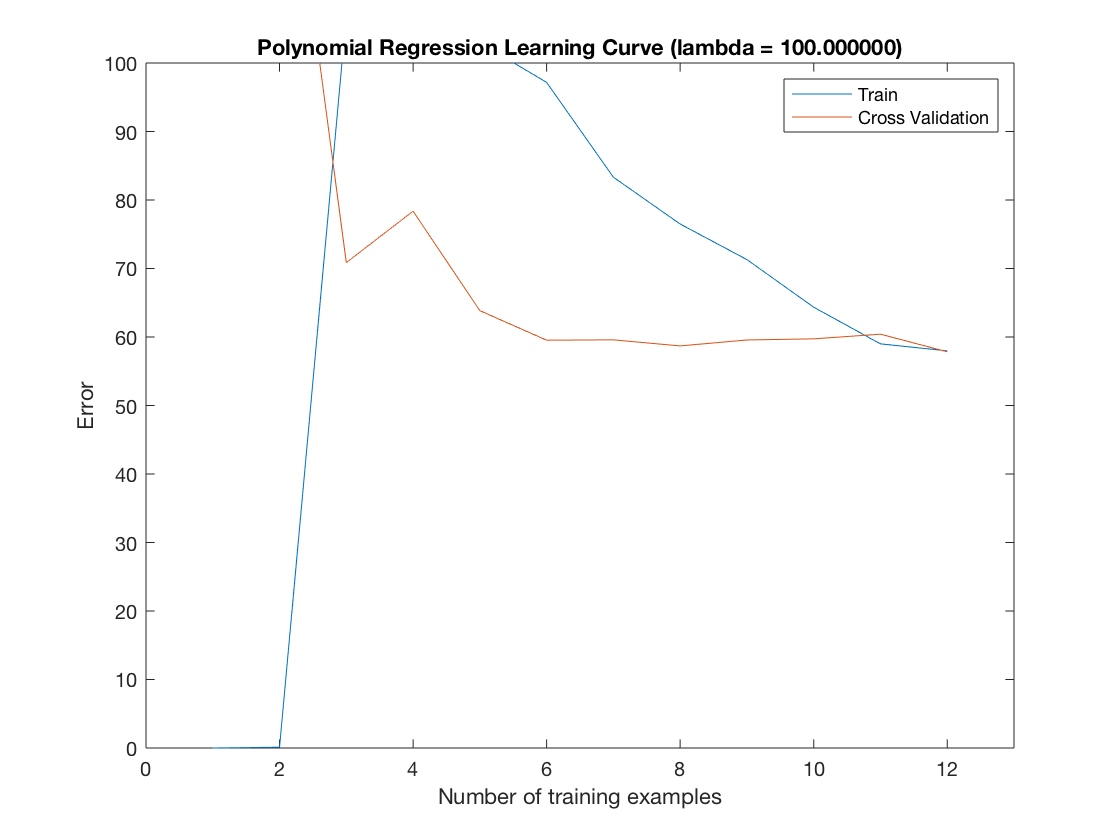

plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

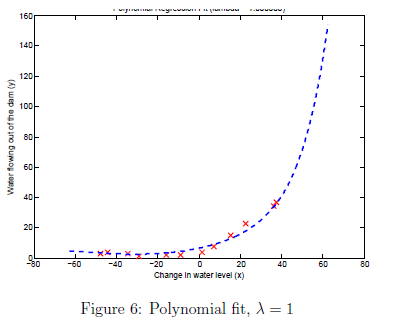

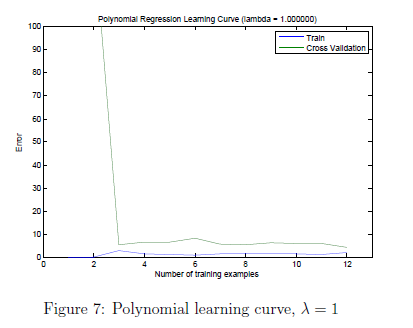

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

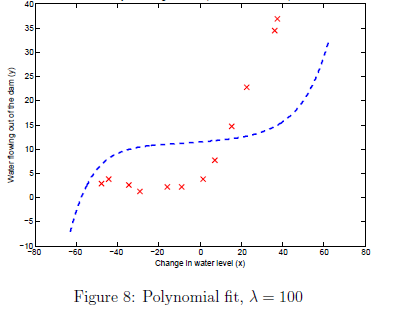

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

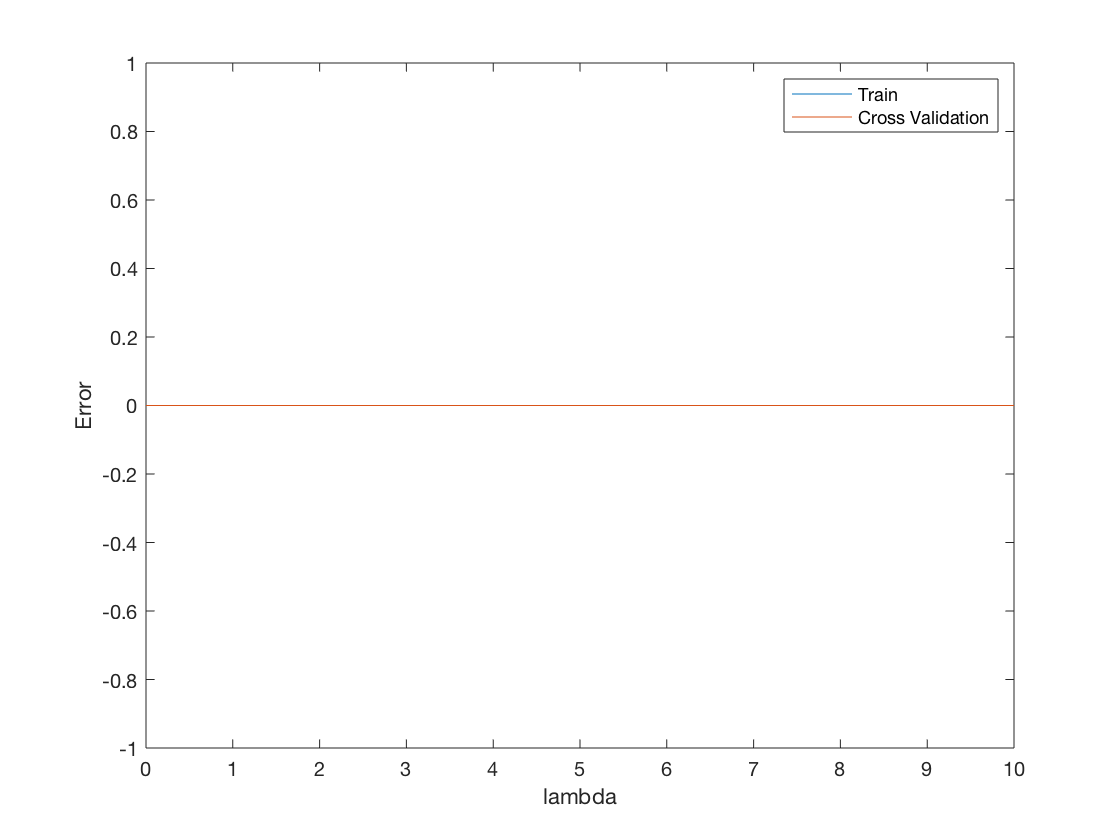

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.000000	0.000000
0.001000	0.000000	0.000000
0.003000	0.000000	0.000000
0.010000	0.000000	0.000000
0.030000	0.000000	0.000000
0.100000	0.000000	0.000000
0.300000	0.000000	0.000000
1.000000	0.000000	0.000000
3.000000	0.000000	0.000000
10.000000	0.000000	0.000000


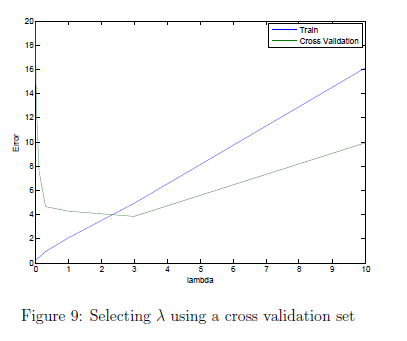

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

Iteration     1 | Cost: 3.405390e-01
Iteration     2 | Cost: 4.988078e-03
Iteration     3 | Cost: 2.151804e-04
Iteration     4 | Cost: 1.111526e-04
Iteration     5 | Cost: 5.971823e-05
Iteration     6 | Cost: 1.149113e-06
Iteration     7 | Cost: 1.118191e-06
Iteration     8 | Cost: 5.589559e-07
Iteration     9 | Cost: 2.324464e-08
Iteration    10 | Cost: 2.323681e-08
Iteration    11 | Cost: 2.302666e-08
Iteration    12 | Cost: 1.565767e-09
Iteration    13 | Cost: 1.565301e-09
Iteration    14 | Cost: 1.550797e-09
Iteration    15 | Cost: 1.155014e-09
Iteration    16 | Cost: 3.935449e-11
Iteration    17 | Cost: 7.973210e-12
Iteration    18 | Cost: 3.407584e-12
Iteration    19 | Cost: 3.935525e-13
Iteration    20 | Cost: 1.649361e-14
Iteration    21 | Cost: 4.690652e-15
Iteration    22 | Cost: 6.854626e-18
Iteration    23 | Cost: 6.829517e-18
Iteration    24 | Cost: 6.793342e-18
Iteration    25 | Cost: 6.629255e-18
Iteration    26 | Cost: 4.750809e-18
Iteration    27 | Cost: 2.573025e-18
I

theta =     2.1343
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000


Iteration     1 | Cost: 5.523568e-02
Iteration     2 | Cost: 3.367312e-03
Iteration     3 | Cost: 3.037007e-03
Iteration     4 | Cost: 2.999639e-03
Iteration     5 | Cost: 2.990979e-03
Iteration     6 | Cost: 2.336617e-03
Iteration     7 | Cost: 2.123237e-03
Iteration     8 | Cost: 1.936561e-03
Iteration     9 | Cost: 1.936559e-03
Iteration    10 | Cost: 1.934948e-03
Iteration    11 | Cost: 1.934845e-03
Iteration    12 | Cost: 1.934800e-03
Iteration    13 | Cost: 1.933872e-03
Iteration    14 | Cost: 1.932846e-03
Iteration    15 | Cost: 1.930444e-03
Iteration    16 | Cost: 1.930286e-03
Iteration    17 | Cost: 1.930061e-03
Iteration    18 | Cost: 1.930051e-03
Iteration    19 | Cost: 1.930045e-03
Iteration    20 | Cost: 1.930039e-03
Iteration    21 | Cost: 1.930039e-03
Iteration    22 | Cost: 1.930039e-03
Iteration    23 | Cost: 1.930038e-03
Iteration    24 | Cost: 1.930038e-03
Iteration    25 | Cost: 1.930037e-03
Iteration    26 | Cost: 1.930037e-03
Iteration    27 | Cost: 1.930036e-03
I

theta =     1.3427
    0.3543
   -0.6076
    0.3455
   -0.3046
    0.1713
   -0.1246
    0.0716
   -0.0479


Iteration     1 | Cost: 3.032734e+01
Iteration     2 | Cost: 1.226927e+00
Iteration     3 | Cost: 7.383164e-01
Iteration     4 | Cost: 2.727993e-01
Iteration     5 | Cost: 2.622976e-01
Iteration     6 | Cost: 2.616915e-01
Iteration     7 | Cost: 2.612460e-01
Iteration     8 | Cost: 2.600987e-01
Iteration     9 | Cost: 2.597820e-01
Iteration    10 | Cost: 2.293193e-01
Iteration    11 | Cost: 2.245222e-01
Iteration    12 | Cost: 2.233166e-01
Iteration    13 | Cost: 2.216354e-01
Iteration    14 | Cost: 2.211828e-01
Iteration    15 | Cost: 2.208628e-01
Iteration    16 | Cost: 2.207706e-01
Iteration    17 | Cost: 2.207157e-01
Iteration    18 | Cost: 2.206993e-01
Iteration    19 | Cost: 2.206900e-01
Iteration    20 | Cost: 2.206839e-01
Iteration    21 | Cost: 2.206779e-01
Iteration    22 | Cost: 2.206654e-01
Iteration    23 | Cost: 2.206531e-01
Iteration    24 | Cost: 2.206316e-01
Iteration    25 | Cost: 2.206176e-01
Iteration    26 | Cost: 2.206125e-01
Iteration    27 | Cost: 2.205933e-01
I

theta =    10.3722
    7.5519
    4.6101
    4.8100
    3.4476
    2.9634
    2.1801
    1.7719
    1.3079


Iteration     1 | Cost: 9.871955e-01
Iteration     2 | Cost: 3.772825e-01
Iteration     3 | Cost: 2.193567e-01
Iteration     4 | Cost: 1.925157e-01
Iteration     5 | Cost: 1.805322e-01
Iteration     6 | Cost: 1.737281e-01
Iteration     7 | Cost: 1.698168e-01
Iteration     8 | Cost: 1.698001e-01
Iteration     9 | Cost: 1.697665e-01
Iteration    10 | Cost: 1.696779e-01
Iteration    11 | Cost: 1.696638e-01
Iteration    12 | Cost: 1.691695e-01
Iteration    13 | Cost: 1.691657e-01
Iteration    14 | Cost: 1.691603e-01
Iteration    15 | Cost: 1.691490e-01
Iteration    16 | Cost: 1.691438e-01
Iteration    17 | Cost: 1.691410e-01
Iteration    18 | Cost: 1.691401e-01
Iteration    19 | Cost: 1.691388e-01
Iteration    20 | Cost: 1.691370e-01
Iteration    21 | Cost: 1.691346e-01
Iteration    22 | Cost: 1.691328e-01
Iteration    23 | Cost: 1.691319e-01
Iteration    24 | Cost: 1.691266e-01
Iteration    25 | Cost: 1.691190e-01
Iteration    26 | Cost: 1.691153e-01
Iteration    27 | Cost: 1.691149e-01
I

theta =    10.4686
    8.2460
    4.9300
    4.5512
    3.1371
    2.3884
    1.6155
    1.1610
    0.7408


Iteration     1 | Cost: 9.146884e+01
Iteration     2 | Cost: 2.717683e+01
Iteration     3 | Cost: 2.290387e+00
Iteration     4 | Cost: 1.423259e+00
Iteration     5 | Cost: 6.557919e-01
Iteration     6 | Cost: 3.475684e-01
Iteration     7 | Cost: 2.187212e-01
Iteration     8 | Cost: 2.104905e-01
Iteration     9 | Cost: 1.996089e-01
Iteration    10 | Cost: 1.977508e-01
Iteration    11 | Cost: 1.816408e-01
Iteration    12 | Cost: 1.616292e-01
Iteration    13 | Cost: 1.613903e-01
Iteration    14 | Cost: 1.610347e-01
Iteration    15 | Cost: 1.607332e-01
Iteration    16 | Cost: 1.604725e-01
Iteration    17 | Cost: 1.597928e-01
Iteration    18 | Cost: 1.581998e-01
Iteration    19 | Cost: 1.544677e-01
Iteration    20 | Cost: 1.496415e-01
Iteration    21 | Cost: 1.495845e-01
Iteration    22 | Cost: 1.493567e-01
Iteration    23 | Cost: 1.489504e-01
Iteration    24 | Cost: 1.483543e-01
Iteration    25 | Cost: 1.477969e-01
Iteration    26 | Cost: 1.472903e-01
Iteration    27 | Cost: 1.471292e-01
I

theta =    10.4036
    8.2293
    4.9543
    4.5593
    3.1223
    2.4182
    1.5803
    1.2014
    0.6973


Iteration     1 | Cost: 6.690068e+01
Iteration     2 | Cost: 1.226122e+01
Iteration     3 | Cost: 1.918807e+00
Iteration     4 | Cost: 7.408589e-01
Iteration     5 | Cost: 3.343811e-01
Iteration     6 | Cost: 1.632769e-01
Iteration     7 | Cost: 1.622905e-01
Iteration     8 | Cost: 1.614093e-01
Iteration     9 | Cost: 1.607871e-01
Iteration    10 | Cost: 1.603902e-01
Iteration    11 | Cost: 1.595778e-01
Iteration    12 | Cost: 1.584817e-01
Iteration    13 | Cost: 1.578657e-01
Iteration    14 | Cost: 1.577320e-01
Iteration    15 | Cost: 1.574616e-01
Iteration    16 | Cost: 1.572492e-01
Iteration    17 | Cost: 1.568663e-01
Iteration    18 | Cost: 1.565178e-01
Iteration    19 | Cost: 1.563230e-01
Iteration    20 | Cost: 1.562620e-01
Iteration    21 | Cost: 1.560168e-01
Iteration    22 | Cost: 1.558641e-01
Iteration    23 | Cost: 1.558049e-01
Iteration    24 | Cost: 1.553377e-01
Iteration    25 | Cost: 1.548663e-01
Iteration    26 | Cost: 1.503130e-01
Iteration    27 | Cost: 1.474778e-01
I

theta =     9.8145
    6.8955
    6.2773
    6.1727
    2.0493
    2.9139
    1.4441
    0.4525
    1.2670


Iteration     1 | Cost: 7.111306e+01
Iteration     2 | Cost: 6.869819e+00
Iteration     3 | Cost: 6.433545e+00
Iteration     4 | Cost: 3.349788e+00
Iteration     5 | Cost: 1.713253e+00
Iteration     6 | Cost: 1.328358e+00
Iteration     7 | Cost: 1.260090e+00
Iteration     8 | Cost: 1.112746e+00
Iteration     9 | Cost: 7.448400e-01
Iteration    10 | Cost: 7.246652e-01
Iteration    11 | Cost: 6.832278e-01
Iteration    12 | Cost: 5.284868e-01
Iteration    13 | Cost: 3.603136e-01
Iteration    14 | Cost: 3.548691e-01
Iteration    15 | Cost: 3.486959e-01
Iteration    16 | Cost: 3.329901e-01
Iteration    17 | Cost: 3.235990e-01
Iteration    18 | Cost: 3.010354e-01
Iteration    19 | Cost: 2.961401e-01
Iteration    20 | Cost: 2.856433e-01
Iteration    21 | Cost: 2.827289e-01
Iteration    22 | Cost: 2.628056e-01
Iteration    23 | Cost: 2.579390e-01
Iteration    24 | Cost: 2.469631e-01
Iteration    25 | Cost: 2.463072e-01
Iteration    26 | Cost: 2.457436e-01
Iteration    27 | Cost: 2.449638e-01
I

theta =    11.1664
   12.3709
    7.5223
    0.1842
   -0.6894
    1.1494
    0.3075
    1.4649
    1.1811


Iteration     1 | Cost: 6.237381e+01
Iteration     2 | Cost: 3.505418e+00
Iteration     3 | Cost: 2.333459e+00
Iteration     4 | Cost: 1.739200e+00
Iteration     5 | Cost: 1.389723e+00
Iteration     6 | Cost: 1.302405e+00
Iteration     7 | Cost: 1.209965e+00
Iteration     8 | Cost: 9.813765e-01
Iteration     9 | Cost: 9.314346e-01
Iteration    10 | Cost: 8.128771e-01
Iteration    11 | Cost: 7.341278e-01
Iteration    12 | Cost: 6.684916e-01
Iteration    13 | Cost: 5.830631e-01
Iteration    14 | Cost: 4.929695e-01
Iteration    15 | Cost: 4.617321e-01
Iteration    16 | Cost: 4.216677e-01
Iteration    17 | Cost: 4.113277e-01
Iteration    18 | Cost: 3.872020e-01
Iteration    19 | Cost: 3.688509e-01
Iteration    20 | Cost: 3.470586e-01
Iteration    21 | Cost: 3.339365e-01
Iteration    22 | Cost: 3.202277e-01
Iteration    23 | Cost: 3.038466e-01
Iteration    24 | Cost: 2.931595e-01
Iteration    25 | Cost: 2.856924e-01
Iteration    26 | Cost: 2.765687e-01
Iteration    27 | Cost: 2.671788e-01
I

theta =    11.3441
   12.5779
    6.9772
   -0.4123
    0.9303
    0.4670
    0.6720
    2.2676
   -0.3792


Iteration     1 | Cost: 5.925570e+01
Iteration     2 | Cost: 4.777949e+00
Iteration     3 | Cost: 4.371300e+00
Iteration     4 | Cost: 2.386109e+00
Iteration     5 | Cost: 1.918562e+00
Iteration     6 | Cost: 1.447349e+00
Iteration     7 | Cost: 1.422182e+00
Iteration     8 | Cost: 1.406061e+00
Iteration     9 | Cost: 1.353693e+00
Iteration    10 | Cost: 1.252421e+00
Iteration    11 | Cost: 1.213698e+00
Iteration    12 | Cost: 9.125371e-01
Iteration    13 | Cost: 6.807740e-01
Iteration    14 | Cost: 5.861014e-01
Iteration    15 | Cost: 5.503406e-01
Iteration    16 | Cost: 5.020099e-01
Iteration    17 | Cost: 4.842196e-01
Iteration    18 | Cost: 4.796307e-01
Iteration    19 | Cost: 4.637584e-01
Iteration    20 | Cost: 4.637042e-01
Iteration    21 | Cost: 4.622622e-01
Iteration    22 | Cost: 4.602563e-01
Iteration    23 | Cost: 4.567432e-01
Iteration    24 | Cost: 4.543545e-01
Iteration    25 | Cost: 4.519716e-01
Iteration    26 | Cost: 4.422584e-01
Iteration    27 | Cost: 4.380523e-01
I

theta =    10.9755
   11.8292
   10.9114
    2.6604
   -4.1801
   -1.0456
   -0.1376
    0.1662
    0.7314


Iteration     1 | Cost: 5.601835e+01
Iteration     2 | Cost: 2.100417e+00
Iteration     3 | Cost: 1.628627e+00
Iteration     4 | Cost: 1.508200e+00
Iteration     5 | Cost: 1.376450e+00
Iteration     6 | Cost: 1.302136e+00
Iteration     7 | Cost: 1.259733e+00
Iteration     8 | Cost: 9.585792e-01
Iteration     9 | Cost: 7.618541e-01
Iteration    10 | Cost: 7.185964e-01
Iteration    11 | Cost: 5.622237e-01
Iteration    12 | Cost: 4.915142e-01
Iteration    13 | Cost: 4.911782e-01
Iteration    14 | Cost: 4.558174e-01
Iteration    15 | Cost: 4.520317e-01
Iteration    16 | Cost: 4.478006e-01
Iteration    17 | Cost: 4.475250e-01
Iteration    18 | Cost: 4.458593e-01
Iteration    19 | Cost: 4.449588e-01
Iteration    20 | Cost: 4.435448e-01
Iteration    21 | Cost: 4.419445e-01
Iteration    22 | Cost: 4.418396e-01
Iteration    23 | Cost: 4.298547e-01
Iteration    24 | Cost: 4.242484e-01
Iteration    25 | Cost: 4.238390e-01
Iteration    26 | Cost: 4.148011e-01
Iteration    27 | Cost: 4.111390e-01
I

theta =    11.0626
   11.9170
   10.2247
    2.9317
   -2.7868
   -2.0995
    0.8305
    0.4697
   -1.2566


Iteration     1 | Cost: 7.187496e+01
Iteration     2 | Cost: 2.281183e+01
Iteration     3 | Cost: 5.007884e+00
Iteration     4 | Cost: 1.413732e+00
Iteration     5 | Cost: 1.311430e+00
Iteration     6 | Cost: 1.246477e+00
Iteration     7 | Cost: 1.217188e+00
Iteration     8 | Cost: 1.099048e+00
Iteration     9 | Cost: 9.727341e-01
Iteration    10 | Cost: 9.467278e-01
Iteration    11 | Cost: 8.916219e-01
Iteration    12 | Cost: 6.621556e-01
Iteration    13 | Cost: 6.210492e-01
Iteration    14 | Cost: 5.761636e-01
Iteration    15 | Cost: 5.171718e-01
Iteration    16 | Cost: 5.082579e-01
Iteration    17 | Cost: 4.977281e-01
Iteration    18 | Cost: 4.911029e-01
Iteration    19 | Cost: 4.890723e-01
Iteration    20 | Cost: 4.847007e-01
Iteration    21 | Cost: 4.746256e-01
Iteration    22 | Cost: 4.678490e-01
Iteration    23 | Cost: 4.568145e-01
Iteration    24 | Cost: 4.479702e-01
Iteration    25 | Cost: 4.413136e-01
Iteration    26 | Cost: 4.395666e-01
Iteration    27 | Cost: 4.332564e-01
I

theta =    11.0278
   11.7382
   10.4400
    3.4481
   -3.0473
   -2.4599
    0.9276
    0.3655
   -1.3836


Iteration     1 | Cost: 8.273556e+01
Iteration     2 | Cost: 2.689698e+01
Iteration     3 | Cost: 1.330795e+01
Iteration     4 | Cost: 3.522725e+00
Iteration     5 | Cost: 2.931455e+00
Iteration     6 | Cost: 2.460864e+00
Iteration     7 | Cost: 2.422567e+00
Iteration     8 | Cost: 1.963855e+00
Iteration     9 | Cost: 1.844730e+00
Iteration    10 | Cost: 1.349712e+00
Iteration    11 | Cost: 9.937145e-01
Iteration    12 | Cost: 7.218176e-01
Iteration    13 | Cost: 6.306579e-01
Iteration    14 | Cost: 5.634188e-01
Iteration    15 | Cost: 5.604560e-01
Iteration    16 | Cost: 5.520138e-01
Iteration    17 | Cost: 5.476408e-01
Iteration    18 | Cost: 5.356230e-01
Iteration    19 | Cost: 5.323333e-01
Iteration    20 | Cost: 5.285175e-01
Iteration    21 | Cost: 5.248384e-01
Iteration    22 | Cost: 5.109166e-01
Iteration    23 | Cost: 5.056047e-01
Iteration    24 | Cost: 5.037735e-01
Iteration    25 | Cost: 4.983408e-01
Iteration    26 | Cost: 4.946222e-01
Iteration    27 | Cost: 4.875957e-01
I

theta =    11.2176
   12.2188
   12.3879
    5.7525
   -4.6010
   -4.9291
   -0.7776
   -2.0942
   -2.3942


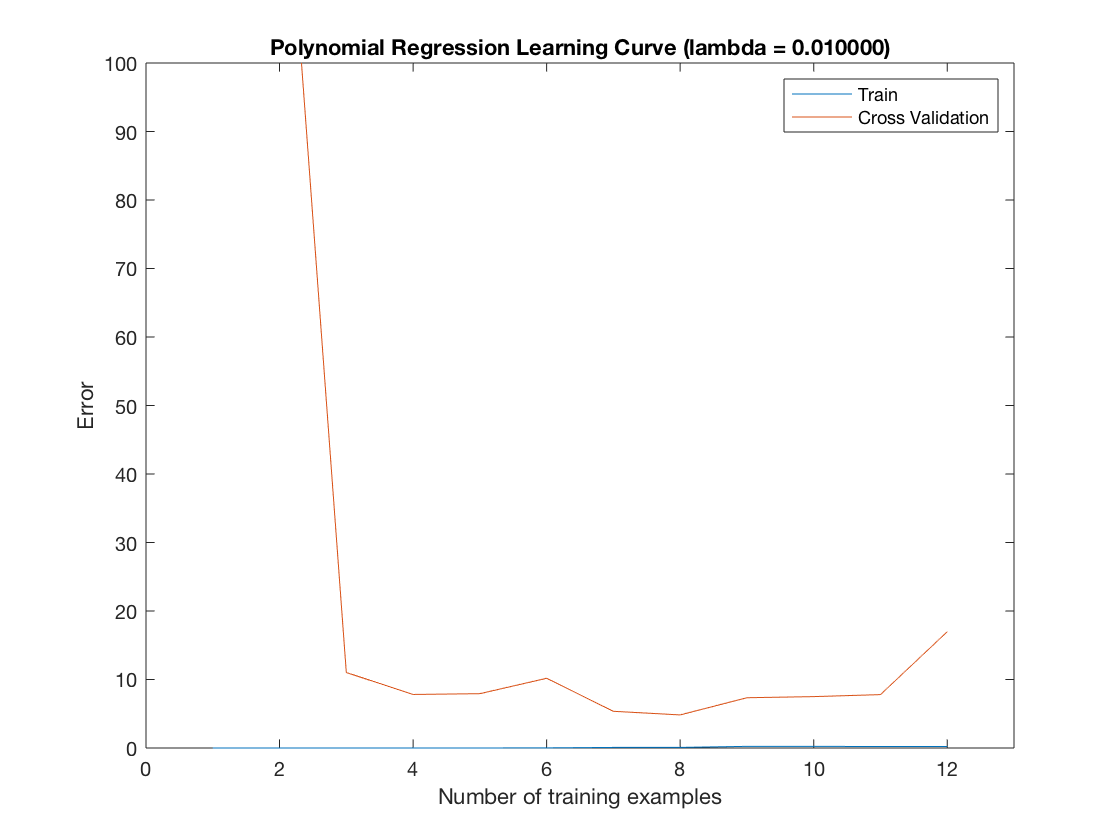

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

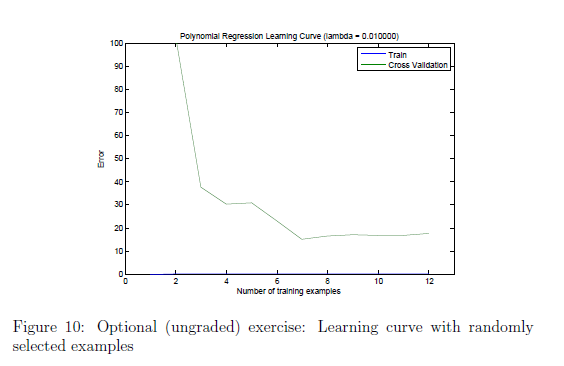

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

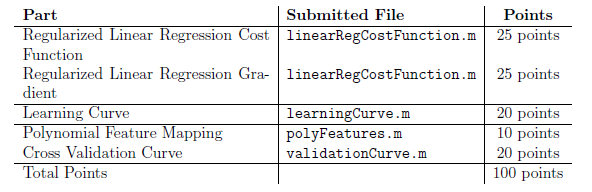

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.